%The script plots the non-dimensional vampire-human model
%Please run Vampire_plot before running this script

% Initial non-dimensional populations
h0 = 1;         % Initial non-dimensional human population
v0 = h0 * SIR_num(2)/SIR_num(1);      % Initial non-dimensional vampire population

SIR_initial_ND = [h0; v0];

% Time step and total simulation time (non-dimensional time)
deltaT_ND = 0.001;          % Time step
tTotal_ND = 2.493;        % Total non-dimensional time

% Color codes for plotting
colorCode = ["#77AC30", "#FF0000"];


% Predict using RK4
t_ND = zeros(1, tTotal_ND / deltaT_ND + 1);
t_ND(1) = 0; % Start with τ = 0
SIR_RK_ND = zeros(length(SIR_initial_ND), tTotal_ND / deltaT_ND + 1);
SIR_RK_ND(:, 1) = SIR_initial_ND;
n = 1;

while t_ND(n) <= tTotal_ND
    SIR_RK_ND(:, n + 1) = SIR_VAM_RK4_ND(deltaT_ND, SIR_RK_ND(:, n), M, N, O, p);
    t_ND(n + 1) = t_ND(n) + deltaT_ND;
    n = n + 1;
end

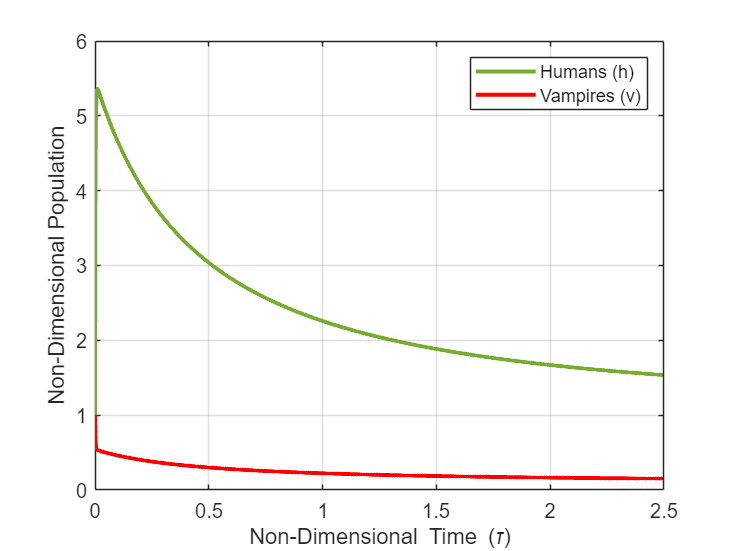


% Plot RK4 Results
figure;
plot(t_ND, SIR_RK_ND(1, :), '-', 'Color', colorCode(1), 'LineWidth', 2); hold on;
plot(t_ND, SIR_RK_ND(2, :), '-', 'Color', colorCode(2), 'LineWidth', 2);
xlabel('Non-Dimensional Time (\tau)');
ylabel('Non-Dimensional Population');
legend('Humans (h)', 'Vampires (v)', 'Location', 'northeast');
%ylim([0 1.2])
%title('Non-Dimensional Human-Vampire Population Dynamics');
grid on;
hold off;

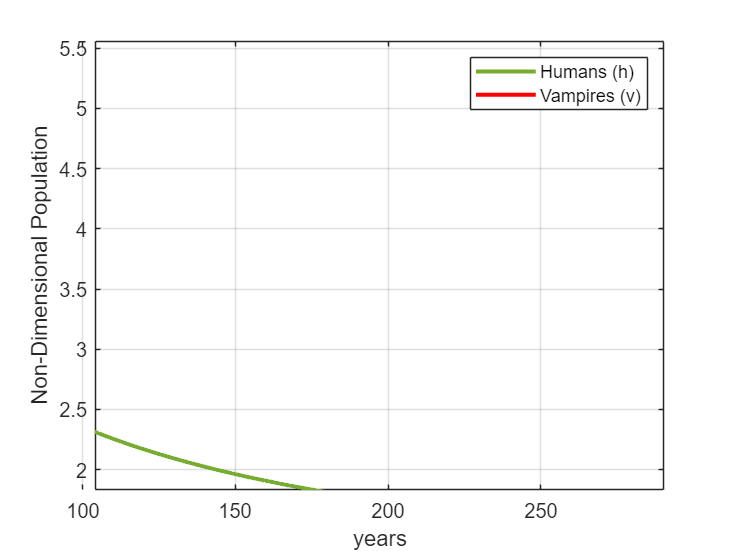


figure;
plot(t_ND/((lambda-ds)*365), SIR_RK_ND(1, :), '-', 'Color', colorCode(1), 'LineWidth', 2); hold on;
plot(t_ND/((lambda-ds)*365), SIR_RK_ND(2, :), '-', 'Color', colorCode(2), 'LineWidth', 2);
xlabel('years');
ylabel('Non-Dimensional Population');
legend('Humans (h)', 'Vampires (v)', 'Location', 'northeast');
%title('Non-Dimensional Human-Vampire Population Dynamics');
grid on;
hold off;

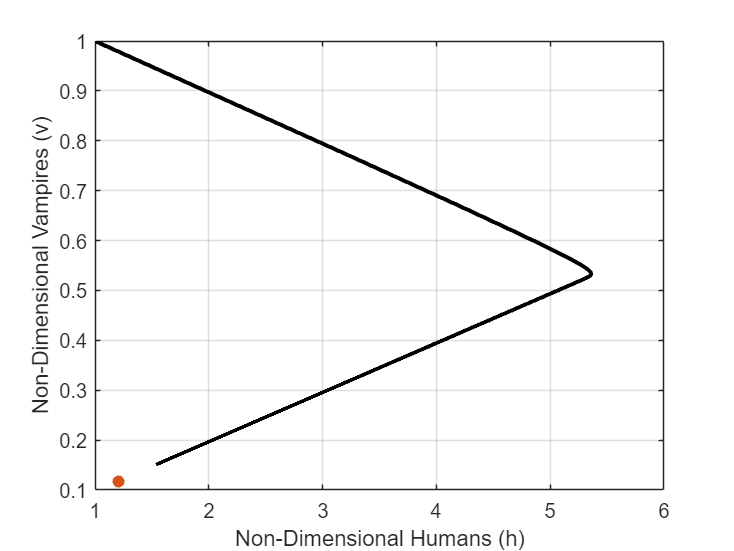


% Phase Plot: Humans vs Vampires
figure;
plot(SIR_RK_ND(1, :), SIR_RK_ND(2, :), 'k-', 'LineWidth', 2);
xlabel('Non-Dimensional Humans (h)');
ylabel('Non-Dimensional Vampires (v)');
%title('Phase Plot: Non-Dimensional Humans vs Vampires');
hold on
scatter(solution(1),solution(2),"filled")
grid on;

%Jacobian
% Define the system of equations
syms h v M_s N_s O_s p_s
f_h = h * (1 - M_s * v * (1 - v / (p_s * h)));
f_v = v * (N_s * h * (1 - v / (p_s * h)) - O_s * v);
% Compute the Jacobian matrix
J = jacobian([f_h, f_v], [h, v]);

% Display the Jacobian matrix
disp('Jacobian Matrix:');

Jacobian Matrix:


disp(J);

$$\begin{array}{l} \left(\begin{array}{cc} M_{s}\,v\,\sigma_{1}-\frac{M_{s}\,v^{2}}{h\,p_{s}}+1 & h\,\left(M_{s}\,\sigma_{1}+\frac{M_{s}\,v}{h\,p_{s}}\right)\\ -v\,\left(N_{s}\,\sigma_{1}-\frac{N_{s}\,v}{h\,p_{s}}\right) & -v\,\left(O_{s}+\frac{N_{s}}{p_{s}}\right)-O_{s}\,v-N_{s}\,h\,\sigma_{1} \end{array}\right)\\ \mathrm{where}\\ \sigma_{1}=\frac{v}{h\,p_{s}}-1 \end{array}$$

% Substitute equilibrium point (h*, v*)
h_star = solution(1);
v_star = solution(2);

% Evaluate the Jacobian at the equilibrium point
J_eval = subs(J, [h, v, M_s, N_s, O_s, p_s], [h_star, v_star, M, N, O, p]);

% Convert symbolic Jacobian to numeric for eigenvalue calculation
J_numeric = double(J_eval);

% Compute eigenvalues of the Jacobian
eigenvalues = eig(J_numeric);

% Display the evaluated Jacobian and eigenvalues
disp('Evaluated Jacobian at the Equilibrium Point:');

Evaluated Jacobian at the Equilibrium Point:


disp(J_numeric);

  -45.7405  457.1864
    4.6741  -47.7624




disp('Eigenvalues of the Jacobian:');

Eigenvalues of the Jacobian:


disp(eigenvalues);

   -0.5136
  -92.9892




% Check stability
if all(real(eigenvalues) < 0)
    disp('The equilibrium point is stable.');
elseif any(real(eigenvalues) > 0)
    disp('The equilibrium point is unstable.');
else
    disp('The equilibrium point is marginally stable.');
end

The equilibrium point is stable.
